# Organize and Analyze Training Data

clear vars; close all; clc;
NUM_NODES = 1628;
OUTPUT_NODE = 1354;
MAX_PCA_MODES = 100;
dt = 0.001;
T = 3.0;

% MODIFY THIS: Set parameters
sample_rate = 1; % In milliseconds

N = T / dt;
Tspan = linspace(0,T,N);
N_divisible = allDivisors(N);
[~, sample_batch] = min(abs(N_divisible - sample_rate));

## Pick Training Data and Consolidate

[files,path] = uigetfile('*.csv',...
   'Select One or More Files', ...
   'MultiSelect', 'on');

% Consolidated data is stored in 'modal_trajectory_data/train_data/output/'
% Make sure to unzip all trajectory csv files into
% 'modal_trajectory_data/train_data/'
[filePath, xData] = consolidateData(path, files, Tspan, ...

Load Data:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf it/s]


    NUM_NODES, sample_batch, 'storeType', 'q');

## PCA on Consolidated Data

% Modify this - change last entry for the mat file you want to PCA
fileForPCA = append(path, 'output/', 'qConsolidatedData.mat');

xPCA = importdata(fileForPCA);

xPCA = 1×2 cell array
    {[0 0.0010 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 0.0330 0.0340 0.0350 0.0360 0.0370 0.0380 0.0390 0.0400 0.0410 0.0420 0.0430 0.0440 0.0450 0.0460 0.0470 0.0480 0.0490 0.0500 0.0510 0.0520 0.0530 0.0540 0.0550 0.0560 0.0570 0.0580 0.0590 0.0600 0.0610 0.0620 0.0630 0.0640 0.0650 0.0660 0.0670 0.0680 0.0690 0.0700 0.0710 0.0720 0.0730 0.0740 0.0750 0.0760 0.0770 0.0780 0.0790 0.0800 0.0810 0.0820 0.0830 0.0840 0.0850 0.0860 0.0870 0.0880 0.0890 0.0900 0.0910 0.0920 0.0930 0.0940 0.0950 0.0960 0.0970 0.0980 0.0990 0.1000 0.1010 0.1020 0.1030 0.1040 0.1050 0.1060 0.1070 0.1080 0.1090 0.1100 0.1110 0.1120 0.1130 0.1140 0.1150 0.1160 0.1170 0.1180 0.1190 0.1200 0.1210 0.1220 0.1230 0.1240 0.1250 0.1260 0.1270 0.1280 0.1290 0.1300 0.1310 0.1320 0.1330 0.1340 0.1350 0.1360 0.1370 0.1380 0.13

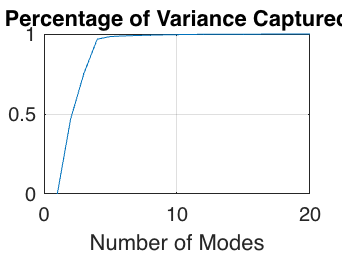

[V, S] = PCA(xPCA, MAX_PCA_MODES);

maxNumModes = 20;
modes = linspace(1, maxNumModes, maxNumModes);
energyFunc = @(x) sum(S(x:end).^2) / sum(S.^2);

figure;
plot(modes, 1 - arrayfun(energyFunc, modes));
grid on;
title('Percentage of Variance Captured');
xlabel('Number of Modes');